# Ephemerides

This script loads an [ephemeris](https://en.wikipedia.org/wiki/Fundamental_ephemeris) from Institute of Applied Astronomy, Russian Academy of Sciences [Online Ephemeris Service](http://iaaras.ru/en/dept/ephemeris/online/#) for solar system planets for 60190 days (1 [Nepture period](https://space-facts.com/orbital-periods-planets/)) begining 29 Oct 2019 for major and leading minor planets. The ephemeris is a 400+ parameter fit to think of it as all observational data and includes the tiny interplanetary gravitational interactions and the space-time distortion associated with SUn as described by the General Theory of Relativity.

Use the script to create a 3d twirlable model of the actual trajectories of objects to get a sense of scale. Observe that the Sun moves in response to the planets (principally Jupiter). Observe the actual trajectories of the Earth and Moon as the Earth-Moon barycenter orbits the Sun. Measure the violations of conservation of the indivdual planet energy and angular momentum and associate those with the planets by computing and removing the force associated with any planet. Use the provided or an extended loaded emphemeris to observe both the short time frame deviations from Kepler's laws and the drift over time of borital parameters to measure for example the precession of apsides.

Author: D. Carlsmith

See also [Online solar system simulator](http://www.orbitsimulator.com/gravity/articles/what.html). Delete planets to see their impact.

### Introduction

A solar system ephemeris summarizes solar system observational data in fit to a smooth empirical motion model. Several recent such ephemerides available online may be used to explore the motions of the planets in detail, in particular to study the perturbations to the independent particle Kepler model due to N-body interactions.

This script loads a 2017 ephemeris and uses MATLAB to plot motions. It examines how well the Kepler model works by examining conservation of orbital angular momentum and energy. With the script, one can explore the impact of the motion of the Sun itself relative to the barycenter and discover quantitatively how much Jupiter influences the motion of the Earth-Moon system.

The script includes a data import function and two ellipse fitting routines from MATLAB FIle Exchange.

### Download data

Visit Institute of Applied Astronomy, Russian Academy of Sciences [Online Ephemeris Service](http://iaaras.ru/en/dept/ephemeris/online/#) to download emphemeris for solar system planets for 60190 days (1 [Neptune period](https://space-facts.com/orbital-periods-planets/)) begining 29 Oct 2019 for major and leading minor planets. For each available object, use exactly the settings below (shown for Venus) and click Show results in a new window. After the page is fully loaded, save as a txt file with filename ObjectName.txt. 

The data are in ecliptic coordinates so the x-yplane is the mean plane of the Earth's orbit, and centered on the solar system barycenter. The x- direction (0° ecliptic longitude) points from the Earth towards the Sun at the vernal [equinox](https://en.wikipedia.org/wiki/Equinox) of the Northern Hemisphere, in the standard epoch [J2000](https://en.wikipedia.org/wiki/Epoch_(astronomy)) ~ 22 Sep. In 2019, the Sep equinox is 23 Sep 7:50 so the start day 2019 10 31 for the data places Earth initial in the upper right quadrant. The winter [solstice](https://en.wikipedia.org/wiki/Solstice) is 2019 22 Dec 4:19.  Earth is closest  to the Sun  January 5, 2020, at 7:48 [Universal Time](https://earthsky.org/astronomy-essentials/universal-time),  2:48 a.m. Eastern Time, 1:48 a.m. Central Time.

The EPM2017 ephmeris fitted object masses are listed at [http://iaaras.ru/en/dept/ephemeris/epm/2017/](http://iaaras.ru/en/dept/ephemeris/epm/2017/) .

The download settings include high accuracy velocities in order to infer acceleration accurately enough to observe the effects of Jupiter.

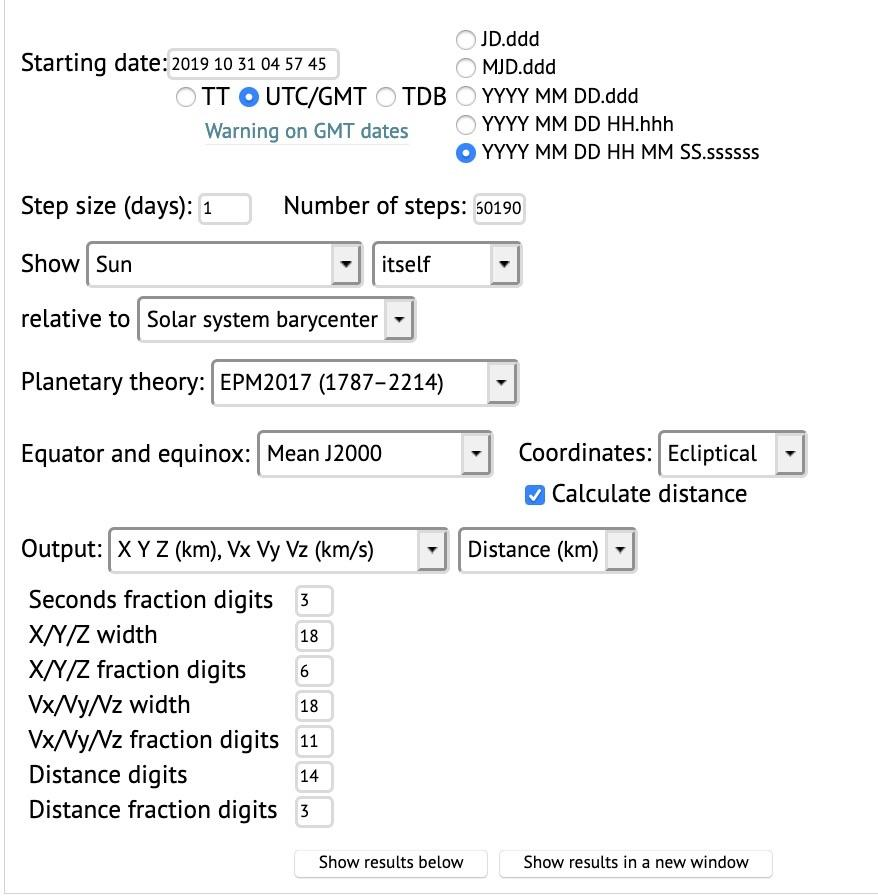

clearvars

### Constants

au=1.495978707e11 ; %  m per au
G= 6.67430e-11;% m^3 kg^(-1) s^(-2)
day=86400;% seconds per day

Object name [string array.](https://www.mathworks.com/help/matlab/ref/string.html#d117e1381672)

objectName=["Sun","Mercury","Venus","Earth","Moon","Mars","Jupiter","Saturn",...
            "Uranus", "Neptune","Pluto","Ceres","Pallas","Vesta"];
nObject=length(objectName);

Constants for Sun and major planets [https://nssdc.gsfc.nasa.gov/planetary/factsheet/](https://nssdc.gsfc.nasa.gov/planetary/factsheet/) and Wikipedia. 

Mass (1e24 kg)

objectMass=[1988470. 0.33010, 4.867, 5.97237, 0.07349, 0.6417, 1898, 568.5,...
    86.82, 102.4, 0.01471, 9.3835e-4 2.01e-4 2.59076e-4];

Mass (kg)

objectMass=objectMass*1e24;

Object mass times G from EPM2017 GM in $km^3/sec^2$converted to $m^3/s$. These are presumably a part of a fit so best to use these.

objectGMass=[ 132712440043.85333,22031.78000,324858.59200,398600.43552,4902.80008,...
    42828.37521,126712764.13345,37940585.20000,5794556.46575,6836527.10058,975.50118,...
    62.62736,13.59173,17.288245]...
    *10^9;

Orbital period (days)

objectPeriod=[0 88.0  224.7  365.2 27.3 687.0 4331 10747 30589 59800 90560 ...
    1683.145 1686 1325.654];

Orbital period (s)

objectPeriod=objectPeriod*days;

Orbital inclination (deg)

objectIncl=[0 7.0 3.4 0.0 5.1 1.9 1.3 2.5 0.8 1.8 17.2 ...
    10.594 34.837 6.39234];

Orbital eccentricity

objectEccen=[0 0.205 0.0068 0.0167 0.055 0.0934 0.0484 0.05 0.046 0.011 0.244 0.076 ...
    0.116 0.2305 0.098758];

Orbital obliquity (deg)

objectObliq=[0 0.034 177.4 23.4 6.7 25.2 3.1 26.7 97.8 28.3 122.5 ...
    0 0 0];

### Import data

Set number of Earth years to import from files. 

**Try this**: Two Earth years is enough to see the orbits of the inner planets while the outer planets and hence the Sun's barycenter stay relatively fixed. Increase the number of years to see complete orbits of the outer planets. Files with settings above go 164.8 years. For longer periods, download replacement files from the Ephemerides service.

nyear=2;
nday=365*nyear;
nday=min(nday,60190)

nday = 730

Set import starting row to skip over the header in the text file and ending row to correspond to number of days.

startRow=9;endRow=startRow+nday;

Loop over objects, import the data into individual data files, and aggregate variables in arrays.

for iObject=1:nObject        

Build file name using [strcat](https://www.mathworks.com/help/matlab/ref/strcat.html), and import using attached function, autogenerated by MATLAB Import tool. Note the quantities and number of digits must match those specified above or a new import function must be used.

    filename=strcat(objectName(iObject),'.','txt');
    ObjectTable=importfileMars(filename,startRow,endRow);   

Convert data for file table to array with [table2array](https://www.mathworks.com/help/matlab/ref/table2array.html) and then add data to arrays for variables.

    Object=table2array(ObjectTable);
    YY(:,iObject)=Object(:,1);%year
    MM(:,iObject)=Object(:,2);%month
    DD(:,iObject)=Object(:,3);%day
    HH(:,iObject)=Object(:,4);%hour
    MM(:,iObject)=Object(:,5);%min
    SS(:,iObject)=Object(:,6);%s
    X(:,iObject)=Object(:,7)*1e3;%x (m)
    Y(:,iObject)=Object(:,8)*1e3;%y (m)
    Z(:,iObject)=Object(:,9)*1e3;%z (m)
    VX(:,iObject)=Object(:,10)*1e3;%vx (m/s)
    VY(:,iObject)=Object(:,11)*1e3;%vy (m/s)
    VZ(:,iObject)=Object(:,12)*1e3;%vz (m/s)
    R(:,iObject)=Object(:,13)*1e3;%distance (m)
end

Build an Earth-Moon barycenter object. Use EPM2017 GM values to location the barycenter.

if nObject>4
    nObject=nObject+1;
    iObject=nObject;
    jObject=4;
    kObject=jObject+1;
    
    mtot=objectGMass(jObject)+objectGMass(kObject);
    objectMass(iObject)=mtot/G;
    objectName(iObject)="EMbarycenter";
    f1=objectGMass(jObject)/mtot;f2=objectGMass(kObject)/mtot;
    
    YY(:,iObject)=YY(:,jObject);
    MM(:,iObject)=MM(:,jObject);
    DD(:,iObject)=DD(:,jObject);
    HH(:,iObject)=HH(:,jObject);
    MM(:,iObject)=MM(:,jObject);
    SS(:,iObject)=SS(:,jObject);
    X(:,iObject)=f1*X(:,jObject)+f2*X(:,kObject);
    Y(:,iObject)=f1*Y(:,jObject)+f2*Y(:,kObject);
    Z(:,iObject)=f1*Z(:,jObject)+f2*Z(:,kObject);
    VX(:,iObject)=f1*VX(:,jObject)+f2*VX(:,kObject);
    VY(:,iObject)=f1*VY(:,jObject)+f2*VY(:,kObject);
    VZ(:,iObject)=f1*VZ(:,jObject)+f2*VZ(:,kObject);
    R(:,iObject)=sqrt(X(:,iObject).^2+Y(:,iObject).^2+Z(:,iObject).^2);
    
    objectGMass(iObject)=objectGMass(4)+objectGMass(5);
end

### Plot solar system orbits in 3d

The 3d solar system containing all objects includes outer planets and a quite small inner core of inner planets. One can zoom the 3d plot. However panning and zooming in 3d can get cumbersome. To view the small variations of an orbit in 3d, load just the Sun and the object and plot the object's orbit over many years. It is helpful in so doing to turn on and off lines connecting the dots to see or not the time correlation.

Set objects display flags (1=true,0=false) to all true by default.

nSolarObject=0;
solarplot=ones(nObject);

**Try this**: To plot Earth, Moon, and Earth-Moon barycenter, uncomment the following.

solarplot=zeros(nObject);
solarplot(4)=1;
solarplot(5)=1;
solarplot(nObject)=1;

Initialize legend string to empty.

figure
legstr=[];

Loop over objects. If display flag true, plot using [plot3](https://www.mathworks.com/help/matlab/ref/plot3.html), increment displayed objects counter, and add to the legend.

for iObject=1:nObject
    if solarplot(iObject)==1
        nSolarObject=nSolarObject+1;
        plot3(X(:,iObject)/au,Y(:,iObject)/au,Z(:,iObject)/au,'.-')
        legstr=cat(1,legstr,objectName(iObject));
    end
    hold on
end

Add the number of objects displayed to the title using [num2str.](https://www.mathworks.com/help/matlab/ref/num2str.html)

title(strcat('Solar System:',num2str(nSolarObject),' objects'))
xlabel('x (au)');ylabel('y (au)');zlabel('z (au)')
legend(legstr,'Location','best')

Set up square axes with equal length in all three dimensions.

axis equal
axis square
h = get(gca,'DataAspectRatio') ;
set(gca,'DataAspectRatio',[1 1 h(1)/h(3)])

View from normal to XY-plane. 

view(0,90)  % XY

**Try this**: Twirl the 3d solar system, view from the side to see how planar it is, include your own loaded objects. Zoom in on an orbit to see how closed it is or isn't. Open the figure stand-alone and view plot browser. There you can turn on or off display of any object.

**Try this**: For sucessive views, uncomment the lines following and hit CR in command window.

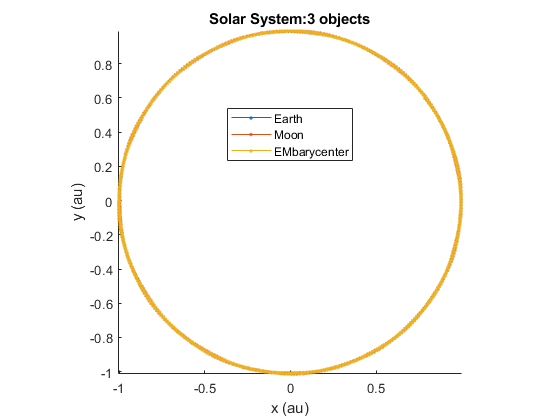

pause

%view(0,0)   % XZ
%pause
%view(90,0)  % YZ

### Plot object's speed and distance from Sun

**Try this**: Select object for which to display speed and distance

iObject=nObject;

**Try this**: To plot distance from solar system barycenter, do not subtract the Sun coordinates below.

x =(X(:,iObject) - X(:,1));
y =(Y(:,iObject) - Y(:,1));
z =(Z(:,iObject) - Z(:,1));

**Try this**: Subtract or not the Sun's velocity to jump to its instantaneous rest frame or not.

vx=VX(:,iObject) - VX(:,1);
vy=VY(:,iObject) - VY(:,1);
vz=VZ(:,iObject) - VZ(:,1);
Xmag=(x.^2+y.^2+z.^2).^(1/2);
meanXmag=mean(Xmag);
Vmag=(vx.^2+vy.^2+vz.^2).^(1/2);
meanVmag=mean(Vmag);

figure
yyaxis left
plot(Xmag/meanXmag,'.-')

Build the title from two strings using [strcat.](https://www.mathworks.com/help/matlab/ref/strcat.html)

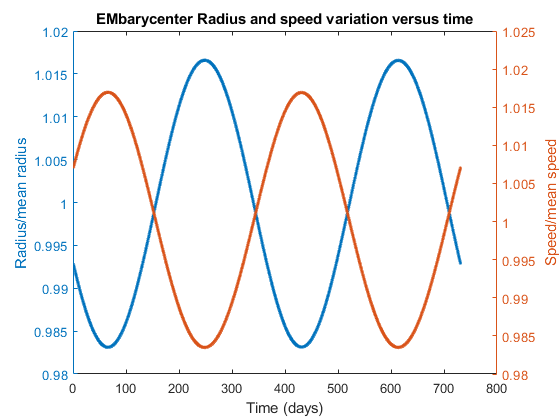

title(strcat(objectName(iObject),' Radius and speed variation versus time'))
xlabel('Time (days)');ylabel('Radius/mean radius')
yyaxis right
plot(Vmag/meanVmag,'.-')
ylabel('Speed/mean speed');

### Plot object kinetic plus solar potential energy. Add perturber potential energies.

Compute kinetic energy plus solar potential energy.

E=(1/2)*Vmag.^2-objectGMass(1)./(Xmag);
meanE=mean(E);
figure
hold on
leg=[];
plot(E/meanE-1,'.-b')
leg=cat(1,leg,objectName(1));

Loop over additional heavy objects and successively add the associated potential energy. We exclude the Earth-Moon barycenter to not double count.

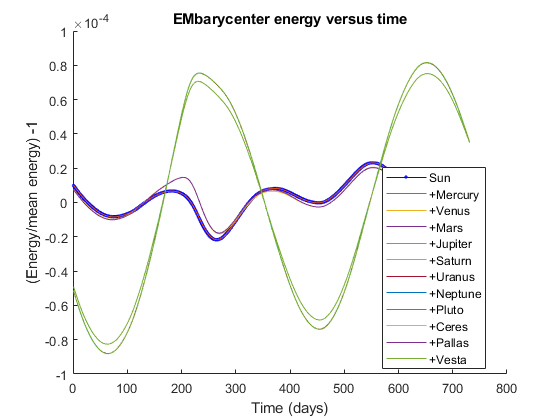

EP=E;
for jObject=2:nObject-1;
    if ~((iObject==nObject)&((jObject==4)|(jObject==5))) 
        if ~(iObject==jObject)
            xP =(X(:,iObject) - X(:,jObject));
            yP =(Y(:,iObject) - Y(:,jObject));
            zP =(Z(:,iObject) - Z(:,jObject));
            XPmag=(xP.^2+yP.^2+zP.^2).^(1/2);
            meanXPmag=mean(XPmag);
            
            EP=EP-objectGMass(jObject)./(XPmag);
            meanEP=mean(EP);
            plot(EP/meanEP-1)
            leg=cat(1,leg,'+'+objectName(jObject));
        end
    end
end
title(strcat(objectName(iObject),' energy versus time'))
xlabel('Time (days)');ylabel('(Energy/mean energy) -1')
legend(leg,'Location',"best")

### Compare object acceleration to gravitational acceleration from Sun and Jupiter

Get position and velocity of object and compute acceleration from velocity differences.

iObject=3;
x =(X(:,iObject) - X(:,1));
y =(Y(:,iObject) - Y(:,1));
z =(Z(:,iObject) - Z(:,1));

**Try this**: Use velocity relative to Sun, or not.

vx=VX(:,iObject) ;%- VX(:,1);
vy=VY(:,iObject) ;%- VY(:,1);
vz=VZ(:,iObject) ;%- VZ(:,1);

Get acceleration using 4th- order central finite difference on velocity. For 1 day between observations of velocity, a (2nd order) central finite difference cannot quite resolve the effect of Jupiter on Mars for which the acceleration due to Jupiter is 1e-4 that of the Sun. The 2nd-order resolves a relative acceleration of 5e-5 and the 4th-order 3e-9 in simulation of the circular order. See stencils at [https://en.wikipedia.org/wiki/Finite_difference_coefficient](https://en.wikipedia.org/wiki/Finite_difference_coefficient) .

To compute the requisite local differences, use [circshift](https://www.mathworks.com/help/matlab/ref/circshift.html) to rotate the elements and subtract vectors.

ax=( (2/3)*circshift(vx,-1)-(1/12)*circshift(vx,-2)-...
    (2/3)*circshift(vx,+1)+(1/12)*circshift(vx,+2) )/day;

Clip off the ends of the vector components for which the finite difference calculation is invalid.

ax=ax(3:end-2);

Repeat for other components.

ay=( (2/3)*circshift(vy,-1)-(1/12)*circshift(vy,-2)-...
    (2/3)*circshift(vy,+1)+(1/12)*circshift(vy,+2) )/day;
ay=ay(3:end-2);
az=((2/3)*circshift(vz,-1)-(1/12)*circshift(vz,-2)-...
    (2/3)*circshift(vz,+1)+(1/12)*circshift(vz,+2) )/day;
az=az(3:end-2);

Plot raw acceleration.

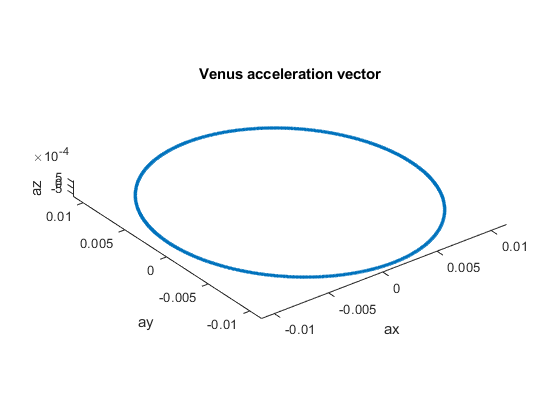

figure
plot3(ax,ay,az,'.')
title(strcat(objectName(iObject),' acceleration vector'))
xlabel('ax');ylabel('ay');zlabel('az')
axis equal

Subtract off acceleration expected due to gravitational force of the Sun and plot residual.

figure
jObject=1;
x=x(3:end-2);y=y(3:end-2);z=z(3:end-2);
Xmag=(x.^2+y.^2+z.^2).^(1/2);
ax=ax+objectGMass(jObject)*x./Xmag.^3;
ay=ay+objectGMass(jObject)*y./Xmag.^3;
az=az+objectGMass(jObject)*z./Xmag.^3;
plot3(ax,ay,az,'.')
title(strcat(objectName(iObject),' acceleration vector (without Sun)'))
xlabel('ax');ylabel('ay');zlabel('az')
axis equal

Compare to expected acceleration due to  Jupiter.

**Try this**:  Saturn is the next contributor. Subtract its influence off also to see the effect of Neptune and then of inner planets.

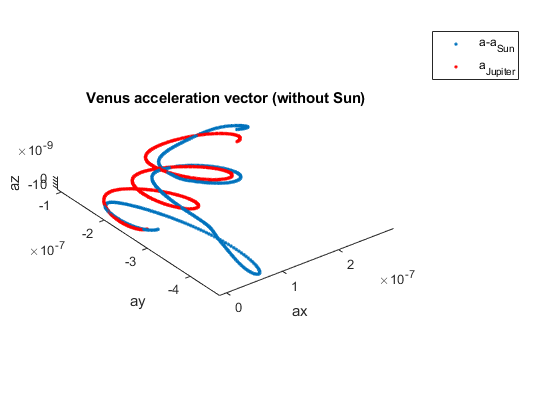

jObject=7;
xj=X(:,jObject)-X(:,iObject);
yj=Y(:,jObject)-Y(:,iObject);
zj=Z(:,jObject)-Z(:,iObject);
xj=xj(3:end-2);yj=yj(3:end-2);zj=zj(3:end-2);
rj=(xj.^2+yj.^2+zj.^2).^(1/2);
ajx=objectGMass(jObject)*xj./rj.^3;
ajy=objectGMass(jObject)*yj./rj.^3;
ajz=objectGMass(jObject)*zj./rj.^3;
hold on
plot3(ajx,ajy,ajz,'.r')
axis equal
legend('a-a_{Sun}','a_{Jupiter}')

**Try this**: Reality check: Compute magnitudes of accelerations for circular orbits.

mp=objectGMass(iObject)/G%planet mass

mp = 4.8673e+24

mS=objectGMass(1)/G% solar mass

mS = 1.9884e+30

mJ=objectGMass(jObject)/G % Jupiter mass

mJ = 1.8985e+27

ap=mean((ax.^2+ay.^2+az.^2).^(1/2)) % mean planet acceleration

ap = 2.5950e-07

vp= mean((vx.^2+vy.^2+vz.^2).^(1/2)) % mean planet speed

vp = 3.5003e+04

rp= mean((x.^2+y.^2+z.^2).^(1/2)) %mean planet orbit radius

rp = 1.0826e+11

rp/au

ans = 0.7237

arp=vp^2/rp% planet centripetal acceleration

arp = 0.0113

ms=objectGMass(1)/G% Sun mass

ms = 1.9884e+30

aps=G*ms/rp^2% expected acceleration

aps = 0.0113

rpj=mean(rj)% mean distance between planet and Jupiter

rpj = 7.6668e+11

rpj/au

ans = 5.1250

apj=objectGMass(jObject)/rpj^2

apj = 2.1557e-07

### Plot object angular momentum per unit mass  ${\bf H}\equiv {\bf x}\times{\bf v}$ .

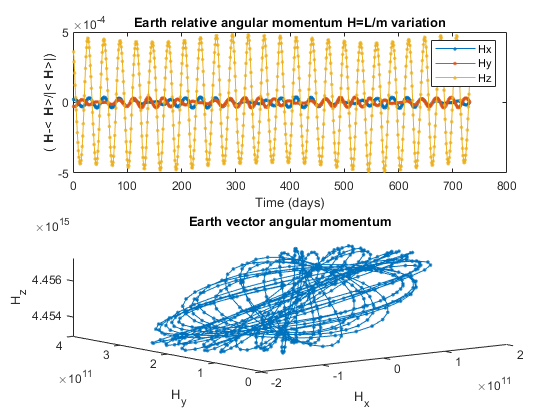

iObject=4;
x =(X(:,iObject) - X(:,1));
y =(Y(:,iObject) - Y(:,1));
z =(Z(:,iObject) - Z(:,1));
vx=(VX(:,iObject) - VX(:,1));
vy=(VY(:,iObject) - VY(:,1));
vz=(VZ(:,iObject) - VZ(:,1));
H=cross([x,y,z],[vx,vy,vz]);
Hmag=abs(H);
figure
subplot(2,1,1)
plot((H-mean(H))/norm(mean(H)),'.-')
title(strcat(objectName(iObject),' relative angular momentum H=L/m variation'))
xlabel('Time (days)');ylabel('({\bf H}-<{\bf H}>/|<{\bf H}>|)')
legend('Hx','Hy','Hz')
subplot(2,1,2)
plot3(H(:,1),H(:,2),H(:,3),'.-')
title(strcat(objectName(iObject),' vector angular momentum '))
xlabel('H_x');ylabel('H_y');zlabel('H_z');

### Plot object eccentricity vector for orbit about the Sun

**Try this**: Were Jupiter the only planet, it would orbit the system barycenter. Examine the eccentricity about the barycenter.

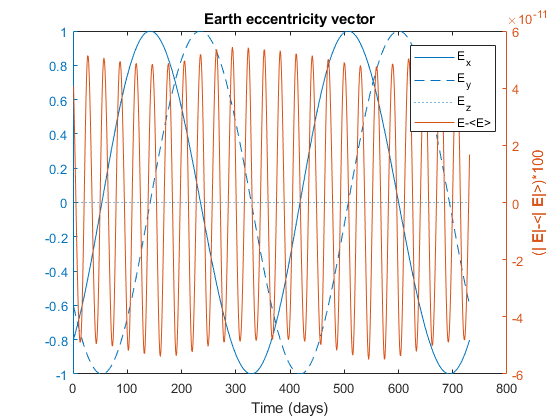

E=H/objectGMass(1)-[x,y,z]./sqrt(x.^2+y.^2+z.^2);
figure
yyaxis left
ylabel('Eccentricity vector components');
xlabel('Time (days)')
plot(E)

legend('E_x','E_y','E_z','Location','best');
hold on
yyaxis right
Emag=(E(:,1).^2+E(:,2).^2+E(:,3).^2).^(1/2);
plot((Emag-mean(Emag))*100)
ylabel('(|{\bf E}|-<|{\bf E}|>)*100')
title(strcat(objectName(iObject),' eccentricity vector'))
legend('E_x','E_y','E_z','E-<E>','Location','best');

### Fit object orbit x and y coordinates to ellipse  

We use the attached functions from FileExchange which an ellipse using only only x and y data.  It would be better to fit all three coordinates x,y,z, or to at least rotate away the orbital inclination. 

**Try this**: See how well the ellipse fitters work with a partial ellipse and with repeated orbits.

iObject=nObject;
x =(X(:,iObject) - X(:,1))/au;
y =(Y(:,iObject) - Y(:,1))/au;
figure
plot(x,y,'.k')
hold on

Call EllipseDirectFit and fit_ellipse and superpose results on ephemeris data.

XY=cat(2,x,y);
[A,x0,y0,a,b,e,phi] = EllipseDirectFit(XY);
f = @(x,y) A(1)*x.^2 +A(2)*x.*y+A(3)*y.^2+A(4)*x+A(5)*y+A(6) ;

Plot EllipseDirectFit results using [fimplicit](https://www.mathworks.com/help/matlab/ref/fimplicit.html).

fimplicit(f,'b')
hold on

Send handle to current plot in calling fit_ellipse to superpose ellipse on the figure.

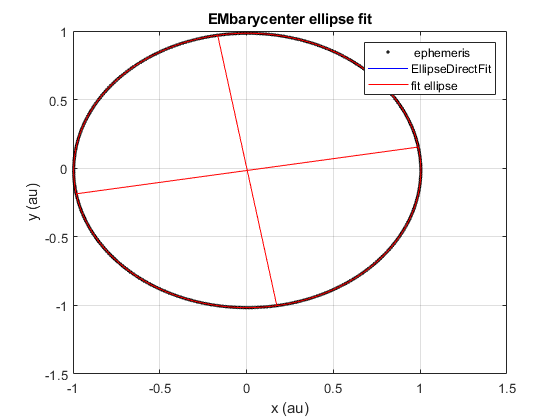

ellipse_t = fit_ellipse( x,y,gca);
xlabel('x (au)');ylabel('y (au)')
title(strcat(objectName(iObject),' ellipse fit '))
legend(' ephemeris','EllipseDirectFit', 'fit ellipse')
grid on

**Try this**: Zoom in to examine differences between the two fitting methods.

Compute eccentricity from min and max radius and the period from the occurance times.

r=sqrt(x.^2+y.^2);
[rmin,Imin]=min(r,[],'linear');
[rmax,Imax]=max(r,[],'linear');
rmax=max(r);
ec=(rmax-rmin)/(rmax+rmin)

ec = 0.0167

period=2*abs(Imin-Imax)

period = 366

### Fit inverse of distance versus angle as expected for elliptical motion about the Sun.

A Keplerian planar ellipse centered on the origin has the radius/angle relation (radius from center not focus)


$$\alpha/r(\theta )= 1+\epsilon\cos(\theta-\theta_0)$$
 

where $\alpha=L^2/(\mu k)$, $L$=angular momentum, $\mu= m_{Sun}m_{object}/(m_{Sun}+m_{object})$=reduced mass,  $k=m_{object}m_{Sun}G_N$, $\theta_0$=angle of minimum distance from the origin, and $\epsilon=\sqrt{1+2EL^2/(\mu k^2)}$=[eccentricity.](https://en.wikipedia.org/wiki/Orbital_eccentricity) The semi-major and semi-minor axes are given by

$a={\alpha\over{1-\epsilon^2}}$ and $b={\alpha\over\sqrt{1-\epsilon^2}}$. 

The apsidal distance (from the Sun) has minimum and maximum values $r_{min/max}=a(1\mp\epsilon)={\alpha\over{1\pm\epsilon}}$. So ${{r_{max}-r_{min}}\over{r_{max}+r_{min}}}= \epsilon$. See e.g. Marion and Thornton, Classical Dynamics, 5th Edition, pg 302.

mdl=@(b,t)b(1)+b(2)*cos(b(3).*t+b(4));

Create polar angle from center and inverse radius. We use the center coordinates from the ellpise fit.

theta=mod(atan2(y-y0,x-x0),2*pi);
s=1./sqrt(x.^2+y.^2);
figure
plot(theta,s,'.')
hold on

Estimate initial parameter values from the plot with a period of 1 year.

b=[mean(s);std(s);1;0.5]

b =     1.0000
    0.0118
    1.0000
    0.5000


fit=fitnlm(theta,s, mdl,b)

fit = Nonlinear regression model:
    y ~ b1 + b2*cos(b3*t + b4)

Estimated Coefficients:
          Estimate         SE          tStat       pValue
          _________    __________    __________    ______

    b1       1.0001    3.8007e-06    2.6315e+05      0   
    b2    -0.016737    5.4533e-06       -3069.2      0   
    b3       1.0014     0.0001714        5842.2      0   
    b4         1.34    0.00059216        2262.9      0   


Number of observations: 731, Error degrees of freedom: 727
Root Mean Squared Error: 0.000101
R-Squared: 1,  Adjusted R-Squared 1
F-statistic vs. constant model: 3.33e+06, p-value = 0

Extract fitted parameter values.

b=fit.Coefficients.Estimate;

Calculate predicted values.

pred=mdl(b,theta);

Overlay fit on plot.

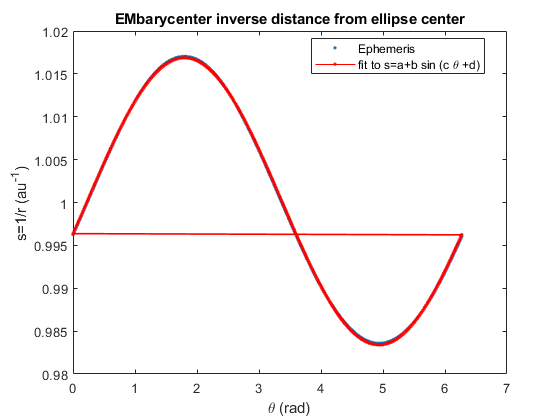

plot(theta,pred,'.r-')
hold on
title(strcat(objectName(iObject),' inverse distance from ellipse center'))
xlabel('\theta (rad)');ylabel('s=1/r (au^{-1})')
legend('Ephemeris','fit to s=a+b sin (c \theta +d)','Location',"best")

### References

Analysis of accuracy of EPM2017 Ephemerides:  Calculation of the  Uncertainties in the Planetary Precessions with the Recent EPM2017  Ephemerides and their Use in Fundamental Physics and Beyond, Lorenzo Iorio, 2019 *AJ* **157** 220, [https://doi.org/10.3847/1538-3881/ab19bf](https://doi.org/10.3847/1538-3881/ab19bf).

An alternate web-based ephemeris service [https://ssd.jpl.nasa.gov/horizons.cgi#top](https://ssd.jpl.nasa.gov/horizons.cgi#top) . Does not supply cartesian coordinates.

[VSOP ephemeris models](https://en.wikipedia.org/wiki/VSOP_(planets))

Constraining the Mass of the Graviton with the Planetary Ephemeris INPOPL. Bernus, O. Minazzoli, A. Fienga, M. Gastineau, J. Laskar, and P. DeramPhys. Rev. Lett. 123, 161103 – Published 18 October 2019, doi = {[10.1103/PhysRevLett.123.161103](https://link.aps.org/doi/10.1103/PhysRevLett.123.161103})}.

[Conversion between ecliptic and equatorial coordinate systems](https://en.wikipedia.org/wiki/Ecliptic_coordinate_system#Conversion_between_celestial_coordinate_systems) , [Obliquity of the ecliptic.](https://en.wikipedia.org/wiki/Ecliptic#Obliquity_of_the_ecliptic)

[NASA Planetary fact sheet](https://nssdc.gsfc.nasa.gov/planetary/factsheet/index.html)

### Reference data

Mercury: 87.97 days (0.2 years)

 Venus : 224.70 days (0.6 years)

 Earth: 365.26 days(1 year)

 Mars: 686.98 days(1.9 years)

 Jupiter: 4,332.82 days (11.9 years)

 Saturn: 10,755.70 days (29.5 years)

 Uranus: 30,687.15 days (84 years)

 Neptune: 60,190.03 days (164.8 years)

[https://www.mathworks.com/matlabcentral/fileexchange/3215-fit_ellipse](https://www.mathworks.com/matlabcentral/fileexchange/3215-fit_ellipse) modified to add ellipse parameters to output

function ellipse_t = fit_ellipse( x,y,axis_handle )
%
% fit_ellipse - finds the best fit to an ellipse for the given set of points.
%
% Format:   ellipse_t = fit_ellipse( x,y,axis_handle )
%
% Input:    x,y         - a set of points in 2 column vectors. AT LEAST 5 points are needed !
%           axis_handle - optional. a handle to an axis, at which the estimated ellipse 
%                         will be drawn along with it's axes
%
% Output:   ellipse_t - structure that defines the best fit to an ellipse
%                       a           - sub axis (radius) of the X axis of the non-tilt ellipse
%                       b           - sub axis (radius) of the Y axis of the non-tilt ellipse
%                       phi         - orientation in radians of the ellipse (tilt)
%                       X0          - center at the X axis of the non-tilt ellipse
%                       Y0          - center at the Y axis of the non-tilt ellipse
%                       X0_in       - center at the X axis of the tilted ellipse
%                       Y0_in       - center at the Y axis of the tilted ellipse
%                       long_axis   - size of the long axis of the ellipse
%                       short_axis  - size of the short axis of the ellipse
%                       theta_r
%                       ellipse_x_r
%                       ellipse_y_r
%                       rotated_ellipse
%                       status      - status of detection of an ellipse
%
% Note:     if an ellipse was not detected (but a parabola or hyperbola), then
%           an empty structure is returned
% =====================================================================================
%                  Ellipse Fit using Least Squares criterion
% =====================================================================================
% We will try to fit the best ellipse to the given measurements. the mathematical
% representation of use will be the CONIC Equation of the Ellipse which is:
% 
%    Ellipse = a*x^2 + b*x*y + c*y^2 + d*x + e*y + f = 0
%   
% The fit-estimation method of use is the Least Squares method (without any weights)
% The estimator is extracted from the following equations:
%
%    g(x,y;A) := a*x^2 + b*x*y + c*y^2 + d*x + e*y = f
%
%    where:
%       A   - is the vector of parameters to be estimated (a,b,c,d,e)
%       x,y - is a single measurement
%
% We will define the cost function to be:
%
%   Cost(A) := (g_c(x_c,y_c;A)-f_c)'*(g_c(x_c,y_c;A)-f_c)
%            = (X*A+f_c)'*(X*A+f_c) 
%            = A'*X'*X*A + 2*f_c'*X*A + N*f^2
%
%   where:
%       g_c(x_c,y_c;A) - vector function of ALL the measurements
%                        each element of g_c() is g(x,y;A)
%       X              - a matrix of the form: [x_c.^2, x_c.*y_c, y_c.^2, x_c, y_c ]
%       f_c            - is actually defined as ones(length(f),1)*f
%
% Derivation of the Cost function with respect to the vector of parameters "A" yields:
%
%   A'*X'*X = -f_c'*X = -f*ones(1,length(f_c))*X = -f*sum(X)
%
% Which yields the estimator:
%
%       ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%       |  A_least_squares = -f*sum(X)/(X'*X) ->(normalize by -f) = sum(X)/(X'*X)  |
%       ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
%
% (We will normalize the variables by (-f) since "f" is unknown and can be accounted for later on)
%  
% NOW, all that is left to do is to extract the parameters from the Conic Equation.
% We will deal the vector A into the variables: (A,B,C,D,E) and assume F = -1;
%
%    Recall the conic representation of an ellipse:
% 
%       A*x^2 + B*x*y + C*y^2 + D*x + E*y + F = 0
% 
% We will check if the ellipse has a tilt (=orientation). The orientation is present
% if the coefficient of the term "x*y" is not zero. If so, we first need to remove the
% tilt of the ellipse.
%
% If the parameter "B" is not equal to zero, then we have an orientation (tilt) to the ellipse.
% we will remove the tilt of the ellipse so as to remain with a conic representation of an 
% ellipse without a tilt, for which the math is more simple:
%
% Non tilt conic rep.:  A`*x^2 + C`*y^2 + D`*x + E`*y + F` = 0
%
% We will remove the orientation using the following substitution:
%   
%   Replace x with cx+sy and y with -sx+cy such that the conic representation is:
%   
%   A(cx+sy)^2 + B(cx+sy)(-sx+cy) + C(-sx+cy)^2 + D(cx+sy) + E(-sx+cy) + F = 0
%
%   where:      c = cos(phi)    ,   s = sin(phi)
%
%   and simplify...
%
%       x^2(A*c^2 - Bcs + Cs^2) + xy(2A*cs +(c^2-s^2)B -2Ccs) + ...
%           y^2(As^2 + Bcs + Cc^2) + x(Dc-Es) + y(Ds+Ec) + F = 0
%
%   The orientation is easily found by the condition of (B_new=0) which results in:
% 
%   2A*cs +(c^2-s^2)B -2Ccs = 0  ==> phi = 1/2 * atan( b/(c-a) )
%   
%   Now the constants   c=cos(phi)  and  s=sin(phi)  can be found, and from them
%   all the other constants A`,C`,D`,E` can be found.
%
%   A` = A*c^2 - B*c*s + C*s^2                  D` = D*c-E*s
%   B` = 2*A*c*s +(c^2-s^2)*B -2*C*c*s = 0      E` = D*s+E*c 
%   C` = A*s^2 + B*c*s + C*c^2
%
% Next, we want the representation of the non-tilted ellipse to be as:
%
%       Ellipse = ( (X-X0)/a )^2 + ( (Y-Y0)/b )^2 = 1
%
%       where:  (X0,Y0) is the center of the ellipse
%               a,b     are the ellipse "radiuses" (or sub-axis)
%
% Using a square completion method we will define:
%       
%       F`` = -F` + (D`^2)/(4*A`) + (E`^2)/(4*C`)
%
%       Such that:    a`*(X-X0)^2 = A`(X^2 + X*D`/A` + (D`/(2*A`))^2 )
%                     c`*(Y-Y0)^2 = C`(Y^2 + Y*E`/C` + (E`/(2*C`))^2 )
%
%       which yields the transformations:
%       
%           X0  =   -D`/(2*A`)
%           Y0  =   -E`/(2*C`)
%           a   =   sqrt( abs( F``/A` ) )
%           b   =   sqrt( abs( F``/C` ) )
%
% And finally we can define the remaining parameters:
%
%   long_axis   = 2 * max( a,b )
%   short_axis  = 2 * min( a,b )
%   Orientation = phi
%
%
% initialize
%orientation_tolerance = 1e-3;
orientation_tolerance = 1e-5;
% empty warning stack
warning( '' );
% prepare vectors, must be column vectors
x = x(:);
y = y(:);
% remove bias of the ellipse - to make matrix inversion more accurate. (will be added later on).
mean_x = mean(x);
mean_y = mean(y);
x = x-mean_x;
y = y-mean_y;
% the estimation for the conic equation of the ellipse
X = [x.^2, x.*y, y.^2, x, y ];
a = sum(X)/(X'*X);
% check for warnings
if ~isempty( lastwarn )
    disp( 'stopped because of a warning regarding matrix inversion' );
    ellipse_t = [];
    return
end
% extract parameters from the conic equation
[a,b,c,d,e] = deal( a(1),a(2),a(3),a(4),a(5) );
% remove the orientation from the ellipse
if ( min(abs(b/a),abs(b/c)) > orientation_tolerance )
    
    orientation_rad = 1/2 * atan( b/(c-a) );
    cos_phi = cos( orientation_rad );
    sin_phi = sin( orientation_rad );
    [a,b,c,d,e] = deal(...
        a*cos_phi^2 - b*cos_phi*sin_phi + c*sin_phi^2,...
        0,...
        a*sin_phi^2 + b*cos_phi*sin_phi + c*cos_phi^2,...
        d*cos_phi - e*sin_phi,...
        d*sin_phi + e*cos_phi );
    [mean_x,mean_y] = deal( ...
        cos_phi*mean_x - sin_phi*mean_y,...
        sin_phi*mean_x + cos_phi*mean_y );
else
    orientation_rad = 0;
    cos_phi = cos( orientation_rad );
    sin_phi = sin( orientation_rad );
end
% check if conic equation represents an ellipse
test = a*c;
switch (1)
case (test>0),  status = '';
case (test==0), status = 'Parabola found';  warning( 'fit_ellipse: Did not locate an ellipse' );
case (test<0),  status = 'Hyperbola found'; warning( 'fit_ellipse: Did not locate an ellipse' );
end
% if we found an ellipse return it's data
if (test>0)
    
    % make sure coefficients are positive as required
    if (a<0), [a,c,d,e] = deal( -a,-c,-d,-e ); end
    
    % final ellipse parameters
    X0          = mean_x - d/2/a;
    Y0          = mean_y - e/2/c;
    F           = 1 + (d^2)/(4*a) + (e^2)/(4*c);
    [a,b]       = deal( sqrt( F/a ),sqrt( F/c ) );    
    long_axis   = 2*max(a,b);
    short_axis  = 2*min(a,b);
    % rotate the axes backwards to find the center point of the original TILTED ellipse
    R           = [ cos_phi sin_phi; -sin_phi cos_phi ];
    P_in        = R * [X0;Y0];
    X0_in       = P_in(1);
    Y0_in       = P_in(2);
    
    % rotation matrix to rotate the axes with respect to an angle phi
    R = [ cos_phi sin_phi; -sin_phi cos_phi ];
    
    % the axes
    ver_line        = [ [X0 X0]; Y0+b*[-1 1] ];
    horz_line       = [ X0+a*[-1 1]; [Y0 Y0] ];
    new_ver_line    = R*ver_line;
    new_horz_line   = R*horz_line;
    
    % the ellipse
    theta_r         = linspace(0,2*pi,1000);
    ellipse_x_r     = X0 + a*cos( theta_r );
    ellipse_y_r     = Y0 + b*sin( theta_r );
    rotated_ellipse = R * [ellipse_x_r;ellipse_y_r];
    
    
    % pack ellipse into a structure
    ellipse_t = struct( ...
        'a',a,...
        'b',b,...
        'phi',orientation_rad,...
        'X0',X0,...
        'Y0',Y0,...
        'X0_in',X0_in,...
        'Y0_in',Y0_in,...
        'long_axis',long_axis,...
        'short_axis',short_axis,...
        'theta_r',theta_r,...
        'ellipse_x_r',ellipse_x_r,...
        'ellipse_y_r',ellipse_y_r,...
        'rotated_ellipse',rotated_ellipse,...
        'status','' );
else
    % report an empty structure
    ellipse_t = struct( ...
        'a',[],...
        'b',[],...
        'phi',[],...
        'X0',[],...
        'Y0',[],...
        'X0_in',[],...
        'Y0_in',[],...
        'long_axis',[],...
        'short_axis',[],...
        'theta_r',[],...
        'ellipse_x_r',[],...
        'ellipse_y_r',[],...
        'rotated_ellipse',[],...
        'status',status );
end
% check if we need to plot an ellipse with it's axes.
if (nargin>2) & ~isempty( axis_handle ) & (test>0)
    
    
    
    % draw
    hold_state = get( axis_handle,'NextPlot' );
    set( axis_handle,'NextPlot','add' );
    plot( new_ver_line(1,:),new_ver_line(2,:),'r' );
    plot( new_horz_line(1,:),new_horz_line(2,:),'r' );
    plot( rotated_ellipse(1,:),rotated_ellipse(2,:),'r' );
    set( axis_handle,'NextPlot',hold_state );
end
end

The following direct fit is from From [https://www.mathworks.com/matlabcentral/fileexchange/22684-ellipse-fit-direct-method](https://www.mathworks.com/matlabcentral/fileexchange/22684-ellipse-fit-direct-method) modified to calculate the center position, semimajor axes, angle and eccentricity using formulae from [Ellipse](https://en.wikipedia.org/wiki/Ellipse#In_Cartesian_coordinates).

function [A,x0,y0,aa,bb,ee,phi] = EllipseDirectFit(XY);
%
%
%  Direct ellipse fit, proposed in article
%    A. W. Fitzgibbon, M. Pilu, R. B. Fisher
%     "Direct Least Squares Fitting of Ellipses"
%     IEEE Trans. PAMI, Vol. 21, pages 476-480 (1999)
%
%  Our code is based on a numerically stable version
%  of this fit published by R. Halir and J. Flusser
%
%     Input:  XY(n,2) is the array of coordinates of n points x(i)=XY(i,1), y(i)=XY(i,2)
%
%     Output: A = [a b c d e f]' is the vector of algebraic 
%             parameters of the fitting ellipse:
%             ax^2 + bxy + cy^2 +dx + ey + f = 0
%             the vector A is normed, so that ||A||=1
%
%  This is a fast non-iterative ellipse fit.
%
%  It returns ellipses only, even if points are
%  better approximated by a hyperbola.
%  It is somewhat biased toward smaller ellipses.
%  
%
centroid = mean(XY);   % the centroid of the data set

D1 = [(XY(:,1)-centroid(1)).^2, (XY(:,1)-centroid(1)).*(XY(:,2)-centroid(2)),...
      (XY(:,2)-centroid(2)).^2];
D2 = [XY(:,1)-centroid(1), XY(:,2)-centroid(2), ones(size(XY,1),1)];
S1 = D1'*D1;
S2 = D1'*D2;
S3 = D2'*D2;
T = -inv(S3)*S2';
M = S1 + S2*T;
M = [M(3,:)./2; -M(2,:); M(1,:)./2];
[evec,eval] = eig(M);
cond = 4*evec(1,:).*evec(3,:)-evec(2,:).^2;
A1 = evec(:,find(cond>0));
A = [A1; T*A1];
A4 = A(4)-2*A(1)*centroid(1)-A(2)*centroid(2);
A5 = A(5)-2*A(3)*centroid(2)-A(2)*centroid(1);
A6 = A(6)+A(1)*centroid(1)^2+A(3)*centroid(2)^2+...
     A(2)*centroid(1)*centroid(2)-A(4)*centroid(1)-A(5)*centroid(2);
A(4) = A4;  A(5) = A5;  A(6) = A6;
%A = A/norm(A);
a=A(1);b=A(2);c=A(3);d=A(4);e=A(5);f=A(6);
t2= b^2-4*a*c;
x0=(2*c*d-b*e)/t2;
y0=(2*a*e-b*d)/t2;
t1=2*(a*e^2+c*d^2-b*d*e+t2*f);

t3=sqrt((a-c)^2+b^2);
aa=abs(-(sqrt(t1)/t2)*sqrt(a+c+t3));
bb=abs(-(sqrt(t1)/t2)*sqrt(a+c-t3));
ee=sqrt(1-(min(abs(bb/aa),abs(aa/bb)))^2);

if abs(b)<eps&a>c
    phi=pi/2;
end
if abs(b)<eps&a<c
    phi=0;
end
if (abs(b)>eps)
    phi=atan(b^(-1)*(c-a-sqrt((a-c)^2+b^2)));
end

end  
%  end of EllipseDirectFit
function Mars = importfileMars(filename, startRow, endRow)
%IMPORTFILE Import numeric data from a text file as a matrix.
%   MARS = IMPORTFILE(FILENAME) Reads data from text file FILENAME for the
%   default selection.
%
%   MARS = IMPORTFILE(FILENAME, STARTROW, ENDROW) Reads data from rows
%   STARTROW through ENDROW of text file FILENAME.
%
% Example:
%   Mars = importfile('Mars.txt', 9, 60199);
%
%    See also TEXTSCAN.

% Auto-generated by MATLAB on 2019/11/03 11:15:43

%% Initialize variables.
if nargin<=2
    startRow = 9;
    endRow = inf;
end

%% Format for each line of text:
%   column1: double (%f)
%	column2: double (%f)
%   column3: double (%f)
%	column4: double (%f)
%   column5: double (%f)
%	column6: double (%f)
%   column7: double (%f)
%	column8: double (%f)
%   column9: double (%f)
%	column10: double (%f)
%   column11: double (%f)
%	column12: double (%f)
%   column13: double (%f)
% For more information, see the TEXTSCAN documentation.
formatSpec = '%4f%3f%3f%3f%3f%7f%19f%19f%19f%19f%19f%19f%f%[^\n\r]';

%% Open the text file.
fileID = fopen(filename,'r');

%% Read columns of data according to the format.
% This call is based on the structure of the file used to generate this
% code. If an error occurs for a different file, try regenerating the code
% from the Import Tool.
textscan(fileID, '%[^\n\r]', startRow(1)-1, 'WhiteSpace', '', 'ReturnOnError', false);
dataArray = textscan(fileID, formatSpec, endRow(1)-startRow(1)+1, 'Delimiter', '', 'WhiteSpace', '', 'TextType', 'string', 'EmptyValue', NaN, 'ReturnOnError', false, 'EndOfLine', '\r\n');
for block=2:length(startRow)
    frewind(fileID);
    textscan(fileID, '%[^\n\r]', startRow(block)-1, 'WhiteSpace', '', 'ReturnOnError', false);
    dataArrayBlock = textscan(fileID, formatSpec, endRow(block)-startRow(block)+1, 'Delimiter', '', 'WhiteSpace', '', 'TextType', 'string', 'EmptyValue', NaN, 'ReturnOnError', false, 'EndOfLine', '\r\n');
    for col=1:length(dataArray)
        dataArray{col} = [dataArray{col};dataArrayBlock{col}];
    end
end

%% Close the text file.
fclose(fileID);

%% Post processing for unimportable data.
% No unimportable data rules were applied during the import, so no post
% processing code is included. To generate code which works for
% unimportable data, select unimportable cells in a file and regenerate the
% script.

%% Create output variable
Mars = table(dataArray{1:end-1}, 'VariableNames', {'YYYY','MM','DD','HH','MM1','SSsss','Xkm','Ykm','Zkm','Vxkms','Vykms','Vzkms','VarName13'});

end